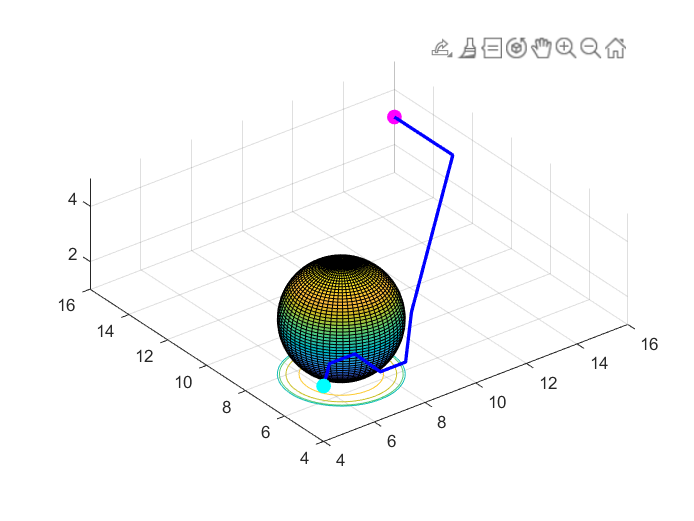

clc;clear;close all;
path1 = csvread("path1.csv");
path2 = csvread("path2.csv");
path3 = csvread("path3.csv");
figure(1);
scatter3(path1(1,1),path1(1,2),path1(1,3),80,"cyan",'filled','o');
hold on;
scatter3(path1(end,1),path1(end,2),path1(end,3),80,"magenta",'filled','o');
b = drawSphere([10,10,3],2);
h = plot3(path1(:,1),path1(:,2),path1(:,3),'LineWidth',2,"Color",'r');
axis equal;
waitforbuttonpress;
delete(h);delete(b);
b = drawSphere([8,8,3],2);
h = plot3(path2(:,1),path2(:,2),path2(:,3),'LineWidth',2,"Color",'b');
axis equal;
waitforbuttonpress;
delete(h);delete(b);
drawSphere([7,7,3],2);
plot3(path3(:,1),path3(:,2),path3(:,3),'LineWidth',2,"Color",'b');
axis equal;

function h = drawSphere(pos, r)
[x,y,z] = sphere(60);
h = surfc(r*x+pos(1), r*y+pos(2), r*z+pos(3));
hold on;
end